# Orientation Tensor Examples

The `p2A` function converts a set of **p** vectors to a second-order orientation tensor, and to a fourth-order tensor if desired.  Because the **p** values are known, this fourth-order tensor is exact.  Here we use `p2A` to do the example calculations from Chapter 2.

The examples use the following fiber arrangements.  All fibers lie in the 1-2 plane.  You must to run these examples from top to bottom to have all the **p** vectors you'll need.  

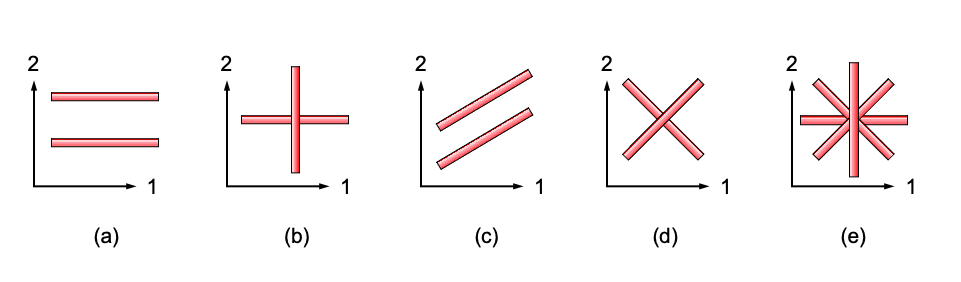

## (a) All fibers at 0$^\circ$

Only one **p** vector is needed, and it should be a 3x1 column vector.  We'll find both the second-order and fourth-order tensors.

fprintf('(a) All fibers at 0 degrees\n')

(a) All fibers at 0 degrees


pzero = [1;0;0]

pzero =      1
     0
     0


[A, A4] = p2A(pzero)

A =      1     0     0
     0     0     0
     0     0     0


A4 =      1     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


(If you can't see the full `A4` matrix, increase the size of your Matlab window).  

## (b) Fibers at 0$^\circ$ and 90$^\circ$

Add another **p** vector and combine them in the input:

fprintf('(b) Fibers at 0 and 90 degrees\n')

(b) Fibers at 0 and 90 degrees


p90 = [0;1;0]

p90 =      0
     1
     0


[A, A4] = p2A([pzero, p90])

A =     0.5000         0         0
         0    0.5000         0
         0         0         0


A4 =     0.5000         0         0         0         0         0
         0    0.5000         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


## (c ) All fibers at 45$^\circ$

The p vector is related to orientation angles by 


$$\mathbf{p} = \left\{ \begin{array}{c} \sin \theta \cos \phi \\ \sin \theta \sin \phi  \\ \cos \theta \end{array} \right\}$$


Using this, for fibers at 45$^\circ$

fprintf('(c) All fibers at 45 degrees\n')

(c) All fibers at 45 degrees


p45 = [cos(pi/4); sin(pi/4); 0]

p45 =     0.7071
    0.7071
         0


[A, A4] = p2A(p45)

A =     0.5000    0.5000         0
    0.5000    0.5000         0
         0         0         0


A4 =     0.2500    0.2500         0         0         0    0.2500
    0.2500    0.2500         0         0         0    0.2500
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
    0.2500    0.2500         0         0         0    0.2500


The fourth-order tensor has some unexpected components in the upper right and lower left corners, but this is the correct tensor.  To see this, use the `rotate4` function (also in Fiber Orientation Tools) to express this tensor in a coordinate system aligned with the fibers:

fprintf('Rotation matrix, 45 degree coordinate rotation\n')

Rotation matrix, 45 degree coordinate rotation


Q = [cos(pi/4), sin(pi/4), 0; -sin(pi/4), cos(pi/4), 0; 0, 0, 1]

Q =     0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000


fprintf('Fourth-order tensor (c), coordinate axes rotated 45 degrees\n')

Fourth-order tensor (c), coordinate axes rotated 45 degrees


A4rot = rotate4(A4, Q)

A4rot =      1     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


This transformed fourth-order tensor is identical to example (a), as it should be. 

## (d) Fibers at $\pm$45$^\circ$

Add a p vector at -45$^\circ$ and combine this with the example above.

fprintf('(d) Fibers at +45 and -45 degrees\n')

(d) Fibers at +45 and -45 degrees


pm45 = [cos(-pi/4); sin(-pi/4); 0]

pm45 =     0.7071
   -0.7071
         0


[A, A4] = p2A([p45, pm45])

A =     0.5000         0         0
         0    0.5000         0
         0         0         0


A4 =     0.2500    0.2500         0         0         0         0
    0.2500    0.2500         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0    0.2500


The second-order tensor is identical to (b) above, but the fourth-order tensors are different.  

If we transform this fourth-order tensor to the coordinate system rotated by 45 degrees, we get the same fourth-order tensor as (b):

fprintf('Fourth-order tensor (d), coordinate axes rotated 45 degrees\n')

Fourth-order tensor (d), coordinate axes rotated 45 degrees


A4rot = rotate4(A4, Q)

A4rot =     0.5000         0         0         0         0         0
         0    0.5000         0         0         0   -0.0000
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0   -0.0000         0         0         0    0.0000


Note that a few of the components have values of 0.0000 or -0.0000.  These are effectively zero (magnitudes around 1e-16) because of truncation errors.

## (e) Fibers at 0, 90, +45 and -45 degrees

Combine the individual fibers from the preceding examples.  

fprintf('(e) Fibers at 0, 90, +45 and -45 degrees\n')

(e) Fibers at 0, 90, +45 and -45 degrees


[A, A4] = p2A([pzero, p90, p45, pm45])

A =     0.5000         0         0
         0    0.5000         0
         0         0         0


A4 =     0.3750    0.1250         0         0         0         0
    0.1250    0.3750         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0    0.1250


Again this has the same second-order tensor as (b) and (d), but a different fourth-order tensor.  This arrangement of fibers is known as a quasi-isotropic layup in the world of laminated, continuous fiber composites.  It has isotropic elastic properties in the 1-2 plane.  We can confirm this by expressing this fourth-order tensor in a coordinate system rotated by any angle in the 1-2 plane, keeping the 3 axis unchanged.  The resulting fourth-order tensor is unchanged.

phid = 27;            % Coordinate axis rotation angle in degrees
phi = deg2rad(phid);  % Coordinate axis rotation angle in radians
fprintf('Coordinate rotation matrix, rotation of %2.0f degrees\n', phid)

Coordinate rotation matrix, rotation of 27 degrees


Q = [cos(phi), sin(phi), 0; -sin(phi), cos(phi), 0; 0, 0, 1]

Q =     0.8910    0.4540         0
   -0.4540    0.8910         0
         0         0    1.0000


fprintf('Fourth-order tensor (e), coordinate axes rotated %2.0f degrees\n', phid)

Fourth-order tensor (e), coordinate axes rotated 27 degrees


A4rot = rotate4(A4, Q)

A4rot =     0.3750    0.1250         0         0         0   -0.0000
    0.1250    0.3750         0         0         0    0.0000
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
    0.0000   -0.0000         0         0         0    0.1250


Try changing the value of `phid` and re-running this section.  The `A4rot` tensor should be the same as the `A4` tensor for this example for any value of `phid`.  